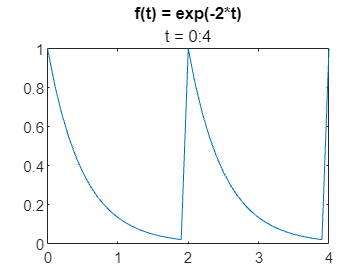

clc; clear; close all;

T = 2;

w = (2*pi)/T;

t = 4;

x = 0:0.1:t;

f_t = exp((-2)*(mod(x,T)));

%figure()
plot(x,f_t)
title("f(t) = exp(-2*t)", "t = 0:"+string(t))

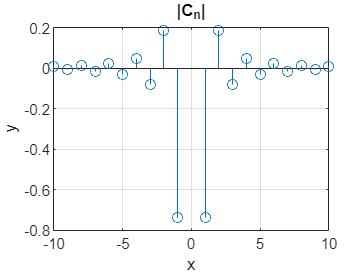


e = exp(1);
r = zeros(-10,10);
c = zeros(-10,10);
t = -10:10;

for n = -10:10
  r(1,n+11)=real(1/2*(e^2*e^(j*n*pi)-e^(-2)*e^(-j*n*pi))*(1/(j*n*pi)+2*1/(n^2*pi^2)));
  c(1,n+11)=imag(1/2*(e^2*e^(j*n*pi)-e^(-2)*e^(-j*n*pi))*(1/(j*n*pi)+2*1/(n^2*pi^2)));
end


stem(t, r)
title("|C_n|")
xlabel("x")
ylabel("y")
grid

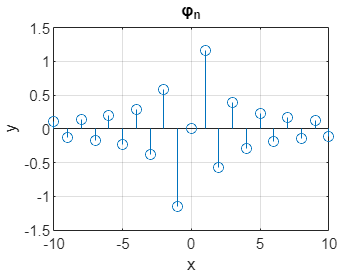

stem(t, c)
title("φ_n")
xlabel("x")
ylabel("y")
grid

clc; clear; close all;

format long

syms r s t

f1=r*r*s

$$f1 = r^{2}\,s$$

f2=r*r*t

$$f2 = r^{2}\,t$$

f3=(s*s)-(t*t)

$$f3 = s^{2}-t^{2}$$


vars = [r,s,t]

$$vars = \left(\begin{array}{ccc} r & s & t \end{array}\right)$$

funcs = [f1,f2,f3]

$$funcs = \left(\begin{array}{ccc} r^{2}\,s & r^{2}\,t & s^{2}-t^{2} \end{array}\right)$$


for i = 1:3
    for j = 1:3
        fprintf(string(funcs(i))+" "+string(vars(j))+":")
        diff(funcs(i),vars(j))
    end
end

r^2*s r:

$$ans = 2\,r\,s$$

r^2*s s:

$$ans = r^{2}$$

r^2*s t:

$$ans = 0$$

r^2*t r:

$$ans = 2\,r\,t$$

r^2*t s:

$$ans = 0$$

r^2*t t:

$$ans = r^{2}$$

s^2 - t^2 r:

$$ans = 0$$

s^2 - t^2 s:

$$ans = 2\,s$$

s^2 - t^2 t:

$$ans = -2\,t$$


J=[6 1 0;
   6 0 1;
   0 6 -6]

J =      6     1     0
     6     0     1
     0     6    -6



points = [1. 3. 3.];
vars = [0.99 3.02 2.97];

dx = transpose(vars - points)

dx =   -0.010000000000000
   0.020000000000000
  -0.030000000000000



df = transpose(J*dx)

df =   -0.040000000000000  -0.090000000000000   0.299999999999999



f(r,s,t)=funcs;

transpose(f(points(1), points(2), points(3))+df)

$$ans = \left(\begin{array}{c} \frac{74}{25}\\ \frac{291}{100}\\ \frac{3}{10} \end{array}\right)$$

var = vpa(ans)

$$var = \left(\begin{array}{c} 2.96\\ 2.91\\ 0.3 \end{array}\right)$$

clc; clear; close all;

[x, y] = meshgrid(0:0.05:1);
z = 2-x-y;

surf(x,y,z)

clc; clear; close all;

syms x y z

$$i1 = x\,\left(x+y-1\right)$$